folder = "11_04_22/uav_data/*.csv";
files = dir(folder);
display(files)

files = 6×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


file_num = 6; %start at 3
file = importdata(files(file_num).folder + "/" + files(file_num).name, ",");
data = file.data(file.data(:,1) < 2000000, :);

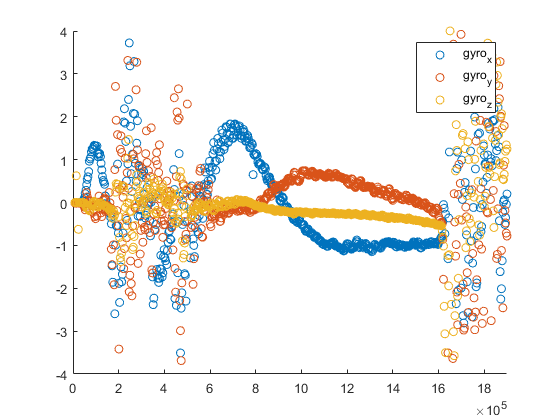

clf
hold on
ylim([-4 4])
xlim([0e6 1.9e6])
scatter(data(:,1), data(:,2))
scatter(data(:,1), data(:,3))
scatter(data(:,1), data(:,4))
legend(file.colheaders(2:4))
hold off

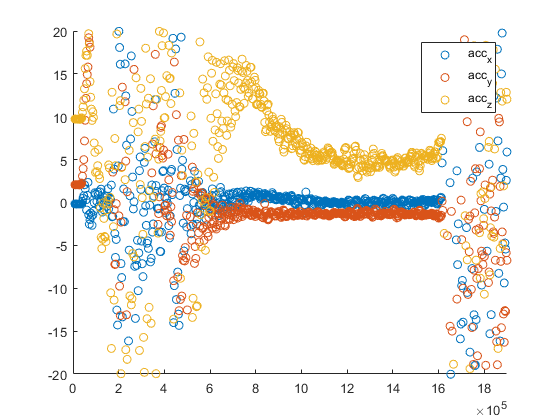

clf
hold on
ylim([-20 20])
xlim([0e6 1.9e6])
scatter(data(:,1), data(:,5))
scatter(data(:,1), data(:,6))
scatter(data(:,1), data(:,7))
legend(file.colheaders(5:7))
hold off

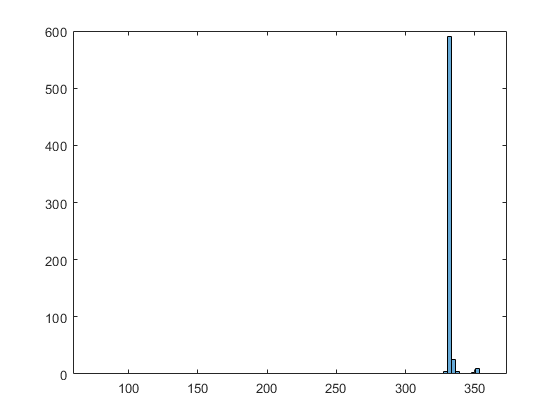

histogram(1000000./diff(data(:,1)), 100)

imu_data = data(data(:,1)>0, :);
% ifilt = imufilter('SampleRate', 333);
% for ii=1:size(imu_data,1)
%     qimu = ifilt(imu_data(ii,5:7), imu_data(ii,2:4));
%     set(poseplot, "Orientation", qimu)
%     drawnow limitrate
% end

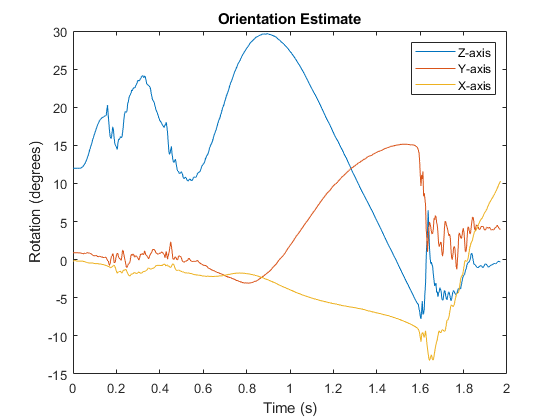

ifilt = imufilter('SampleRate', 333, 'LinearAccelerationDecayFactor', 0.9);
a = ifilt(imu_data(:,5:7), imu_data(:,2:4));

time = (0:1:size(imu_data,1)-1)/333;
plot(time,eulerd(a,'XYZ','frame'))
title('Orientation Estimate')
legend('Z-axis', 'Y-axis', 'X-axis')
xlabel('Time (s)')
ylabel('Rotation (degrees)')